clearvars

# Wind tunnel model 

u1 : flow control, u2 : temperature control

y1 : flow measure, y2 : temperature measure

## Identified model

% H1: ventilation and flow u1 and y1 
H1 = tf([1.053,1.155],[1,1.942,6.112,1.517],'InputDelay',0.1);

% H2: chauffage and flow u2 and y1
H2 = 0;

% H3: ventilation and temperature u1 and y2
H3 = tf([-0.005487,0.02488,0.0264],[1,0.7964,0.1684],'InputDelay',1.7);

% H4: chauffage and temperature u2 and y2
H4 = tf([1.347,0.8525],[1,5.102,9.509,3.071],'InputDelay',0.05);

H = [H1, H2;H3, H4];

# Control model (discrete state space)

choice of a sampling period (keep the notation Te)

Te = 0.05;

% Matlab function to discretize a system
Hd = c2d(H,Te);

Change to state form, and state matrices extraction.

sysd=ss(Hd)

sysd =
 
  A = 
           x1      x2      x3      x4      x5      x6      x7      x8
   x1   2.893    -1.4  0.9075       0       0       0       0       0
   x2       2       0       0       0       0       0       0       0
   x3       0     0.5       0       0       0       0       0       0
   x4       0       0       0   1.961  -0.961       0       0       0
   x5       0       0       0       1       0       0       0       0
   x6       0       0       0       0       0   2.754  -1.264  0.7748
   x7       0       0       0       0       0       2       0       0
   x8       0       0       0       0       0       0     0.5       0
 
  B = 
           u1      u2
   x1  0.0625       0
   x2       0       0
   x3       0       0
   x4  0.0625       0
   x5       0       0
   x6       0  0.0625
   x7       0       0
   x8       0       0
 
  C = 
               x1          x2          x3          x4          x5          x6          x7          x8
   y1     0.02074   0.0004082    -0.

A=sysd.A

A =     2.8928   -1.4002    0.9075         0         0         0         0         0
    2.0000         0         0         0         0         0         0         0
         0    0.5000         0         0         0         0         0         0
         0         0         0    1.9605   -0.9610         0         0         0
         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0    2.7537   -1.2644    0.7748
         0         0         0         0         0    2.0000         0         0
         0         0         0         0         0         0    0.5000         0


B=sysd.B

B =     0.0625         0
         0         0
         0         0
    0.0625         0
         0         0
         0    0.0625
         0         0
         0         0


C=sysd.C

C =     0.0207    0.0004   -0.0194         0         0         0         0         0
         0         0         0    0.0235   -0.0224    0.0250   -0.0005   -0.0225


D=sysd.D

D =          0         0
   -0.0055         0


#### Inclusion of operating points

Inclusion of operating points : ${u}_0(k+1)=u_{0}(k)
$ et $y_0(k+1)=y_0(k)$ 

Aa= [A, -B, zeros(8,2); zeros(2,8), eye(2,2), zeros(2,2); zeros(2,10), eye(2,2)];
Ba= [B; zeros(2,2); zeros(2,2)];
Ca= [C, zeros(2,2), eye(2,2)];

#### Decomposition according to observability

Obsa=obsv(Aa,Ca);
rank(Obsa);
% rank is 10;

There are xx observable modes 

[AO,BO,CO,TO,k]=obsvf(Aa,Ba,Ca);

$T0$  is the basis change matrix (useful for Simulink later)

We get only the observable part

Ao=AO(3:12,3:12);
Bo=BO(3:12,1:2);
Co=CO(1:2,3:12);

Eigenvalues study

eig(Ao)

ans =    0.8868 + 0.0643i
   0.8868 - 0.0643i
   0.9803 + 0.0049i
   0.9803 - 0.0049i
   0.9800 + 0.0000i
   0.9531 + 0.1066i
   0.9531 - 0.1066i
   0.9867 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i


## State observer

Choice of the poles:

poles_obs = eig(Ao);
% poles_obs = exp(-3*Te*[1:1:10]);

Matrice determination

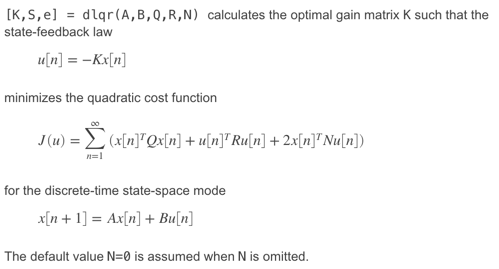

L0 = place(Ao,Bo,poles_obs);
% L0 = dlqr(Ao',Co',0.1*eye(10),eye(2));
L0 = L0';
eig(Ao-L0*Co);

State model of the observer (keep the following notations for simulink)

A_OBS= Ao - L0*Co;
B_OBS= [Bo, L0];
C_OBS= eye(rank(Obsa));
D_OBS= zeros(rank(Obsa), 4);

# Prediction model

Choice of the size of the prediction model

Np=30; % keep the notation Np (required for simulink)

Explicite matrices definition

We want the following model $Y(K+1|k)=Fx(k|k)+HU(K|k)$ 

nx=size(Co*Ao,1); 
% the row number
nc=size(Ao,1);
nu=size(Co*Bo,2);

F=zeros(Np*nx,nc);
H=zeros(Np*nx,Np*nu);

for i=1:Np
    F(nx*(i-1)+1:nx*i,:)=Co*(Ao^i) ;
    for j=1:i
        H(nx*(i-1)+1:nx*i,nu*(j-1)+1:nu*j)=Co*(Ao^(i-j))*Bo;
    end
end

Unitary tests

% 

# Problem construction: energy minimization, under maximum power constraint.

#### Initial conditions:

y1min = 0.2;
y2min = 0.1; 
Ymin_mat = repmat([y1min;y2min],Np,1);

UTOTmax_mat = 20*ones(Np,1);

% u1:flow control; 
% u2:temperature control 

#### Cost function:

1/2 (Y - Ymin)^T (Y - Ymin) + lamda/2 U^T U 

#### Constraints :

lambda_u = 0.1;
lambda_e = 100;

W = [eye(2*Np), zeros(2*Np,5*Np); zeros(2*Np), lambda_u*eye(2*Np), zeros(2*Np,3*Np); zeros(3*Np,4*Np), lambda_e*eye(3*Np)];
f = [-Ymin_mat', zeros(1,5*Np)];

% T*U ≤ UTOTmax
T = zeros(Np,2*Np);
for i = 1:Np
    T(i,2*i-1:2*i) = [1,1];
end

% temp: P*Y2≤R*epsilon + P*Y2min + 2
P = zeros(Np,2*Np);
for i = 1:Np
    P(i,2*i) = 1;
end

Q = zeros(2*Np,3*Np);
for i = 1:Np
    Q(2*i-1,3*i-2) = 1;
    Q(2*i,3*i-1) = 1;
end
% Q = zeros(2*Np,3*Np);

% temp: P*Y2≤R*epsilon + P*Y2min + 2
R = zeros(Np,3*Np);
for i = 1:Np
    R(i,3*i) = 1;
end
% R = zeros(Np,3*Np);

A_quad = [zeros(Np,2*Np), T, zeros(Np,3*Np); -eye(2*Np), zeros(2*Np), -Q; P, zeros(Np,2*Np), -R];
b_quad = [UTOTmax_mat; -Ymin_mat; P*Ymin_mat + 2*ones(Np,1)];

Aeq = [eye(2*Np), -H, zeros(2*Np,3*Np)];

lb = -inf(7*Np,1);
ub = inf(7*Np,1);
lb(2*Np+1:4*Np,1) = 0;
ub(2*Np+1:4*Np,1) = 10;

#### open loop model validation

xinit=0*ones(10,1);
x1 = xinit;

beq = F*x1;
[Zopt] = quadprog(W,f,A_quad,b_quad,Aeq,beq,lb,ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% extracting the input U from Zopt(Y,U,E)
U_mat = Zopt(2*Np+1:4*Np,1);
U1_mat = zeros(Np,2);
for i = 1: Np
    U1_mat(i,1) = U_mat(2*i-1,1);
    U1_mat(i,2) = U_mat(2*i,1);
end

% computing Y
Y_mat = F*xinit+ H*U_mat;
% rewrite Y0 as Y1
Y1_mat = zeros(Np,1);
Y2_mat = zeros(Np,1);
for i = 1: Np
    Y1_mat(i,1) = Y_mat(2*i-1,1);
    Y2_mat(i,1) = Y_mat(2*i,1);
end

U_total = sum(U1_mat,2)

U_total =     7.8293
    5.4482
    3.6045
    2.2566
    1.3373
    0.7660
    0.4577
    0.3279
    0.2970
    0.3080


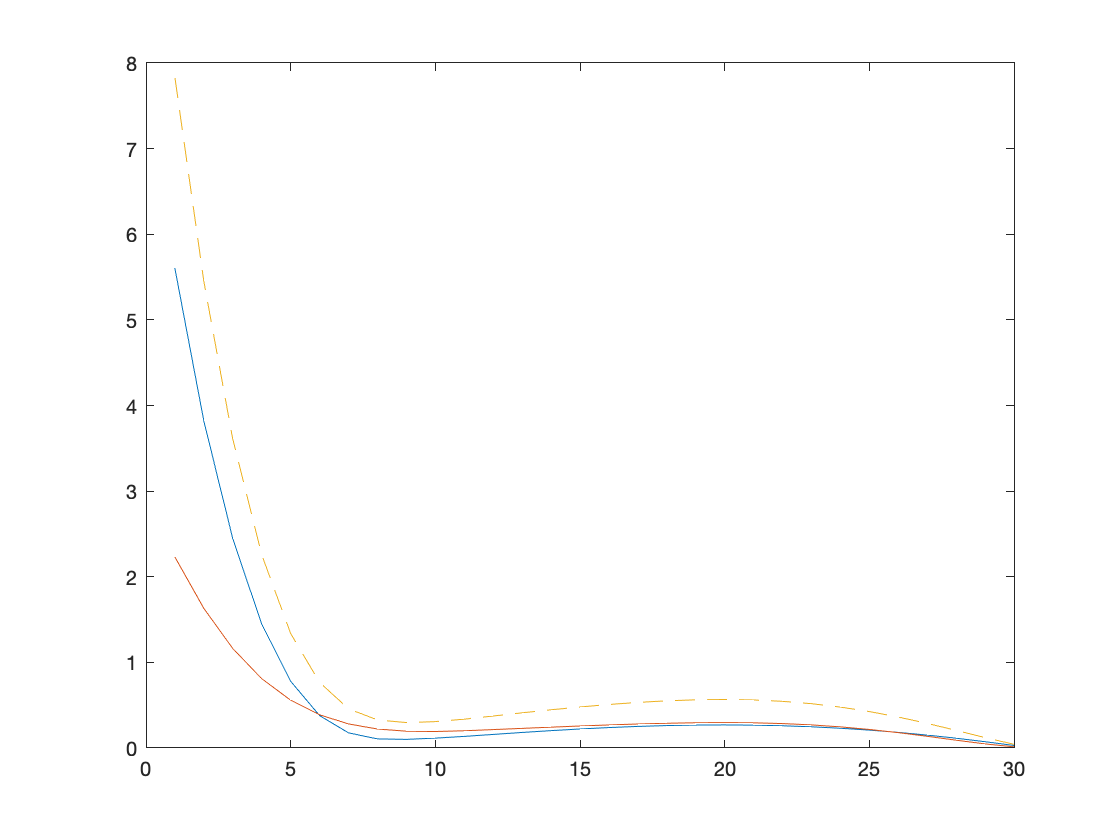


plot(1:Np,U1_mat',1:Np,U_total,'--');

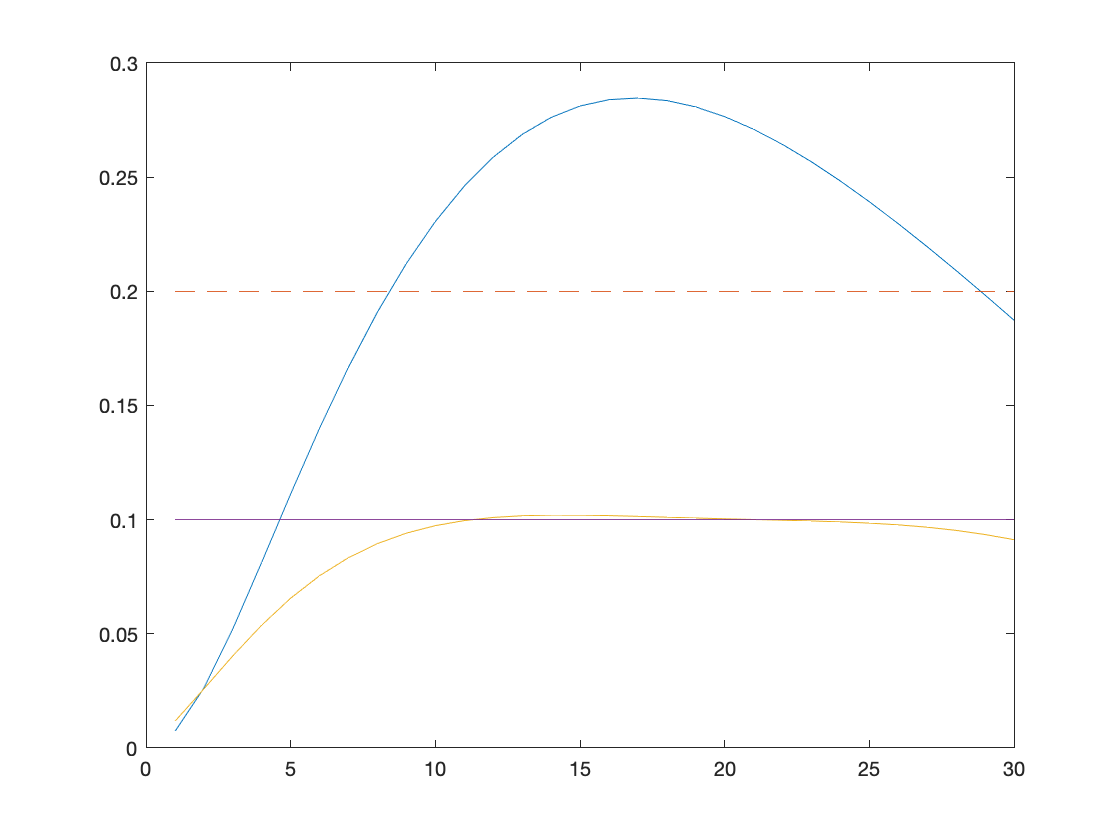

 
plot(1:Np,Y1_mat,1:Np,y1min*ones(Np,1),'--',1:Np,Y2_mat,1:Np,y2min*ones(Np,1));

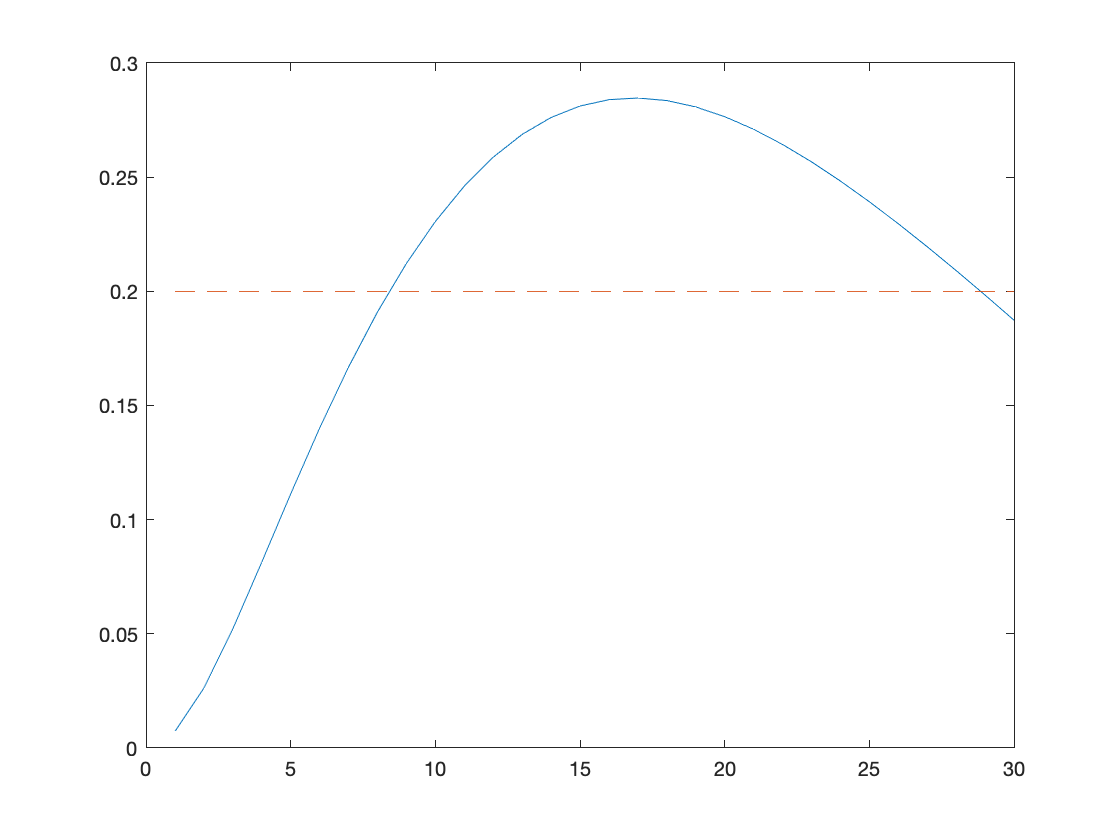


plot(1:Np,Y1_mat,1:Np,y1min*ones(Np,1),'--');

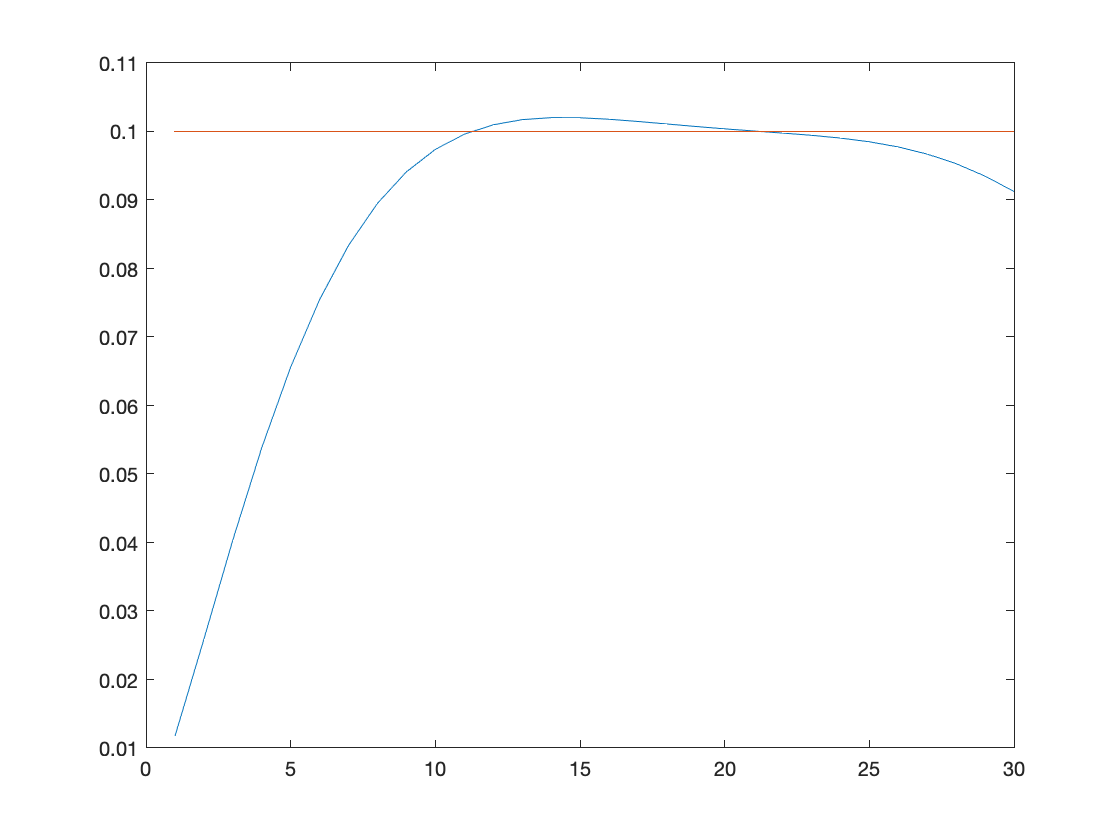

plot(1:Np,Y2_mat,1:Np,y2min*ones(Np,1));%,1:Np,(y2min+2)*ones(Np,1)

# Application into Simulink

Ouvrir et compléter le simulink ('2A_SG8_MPC_simu_MPC_student.slx'). 

You must also compile the following two sections for the Simulink file to be executable.

#### Umax prediction generator

Amaxpred=zeros(Np,Np);
Amaxpred(1:Np-1,2:Np)=eye((Np-1));
Bmaxpred=zeros(Np,1);
Bmaxpred(Np,1)=eye(1);
Cmaxpred=eye(Np);
Dmaxpred=zeros(Np,1);

#### Setpoint generator (corresponding to$Tmin(K+1|k)$ and $Dmin(K+1|k)$)

Arefpred=zeros(2*Np,2*Np);
Arefpred(1:2*(Np-1),3:2*Np)=eye(2*(Np-1));
Brefpred=zeros(2*Np,2);
Brefpred(2*(Np-1)+1:2*Np,:)=eye(2);
Crefpred=Arefpred;
Drefpred=Brefpred;

sysrefpred=ss(Arefpred,Brefpred,Crefpred,Drefpred,Te);

lambda_u = 0.1;
lambda_e = 100;
% sim('SG8_MPC_simu_MPC_student')